% -----------------------------------------
% ICE03
% LiXin
% 2022/3/11
% -----------------------------------------

Problem 1

close all; clear all; clc;
t=60*24*3600;
Ts=-15;
Ti=20;
T=0;
a=1.38e-7;
% solve the equation
syms x
eqn= (T-Ts)/(Ti-Ts)==erf(x/(2*sqrt(a*t)));
solve(eqn, x)

$$ans = \frac{18\,\sqrt{138}\,\mathrm{erfinv}\left(\frac{3}{7}\right)}{125}$$

Problem 2

Fine first two positive values of b

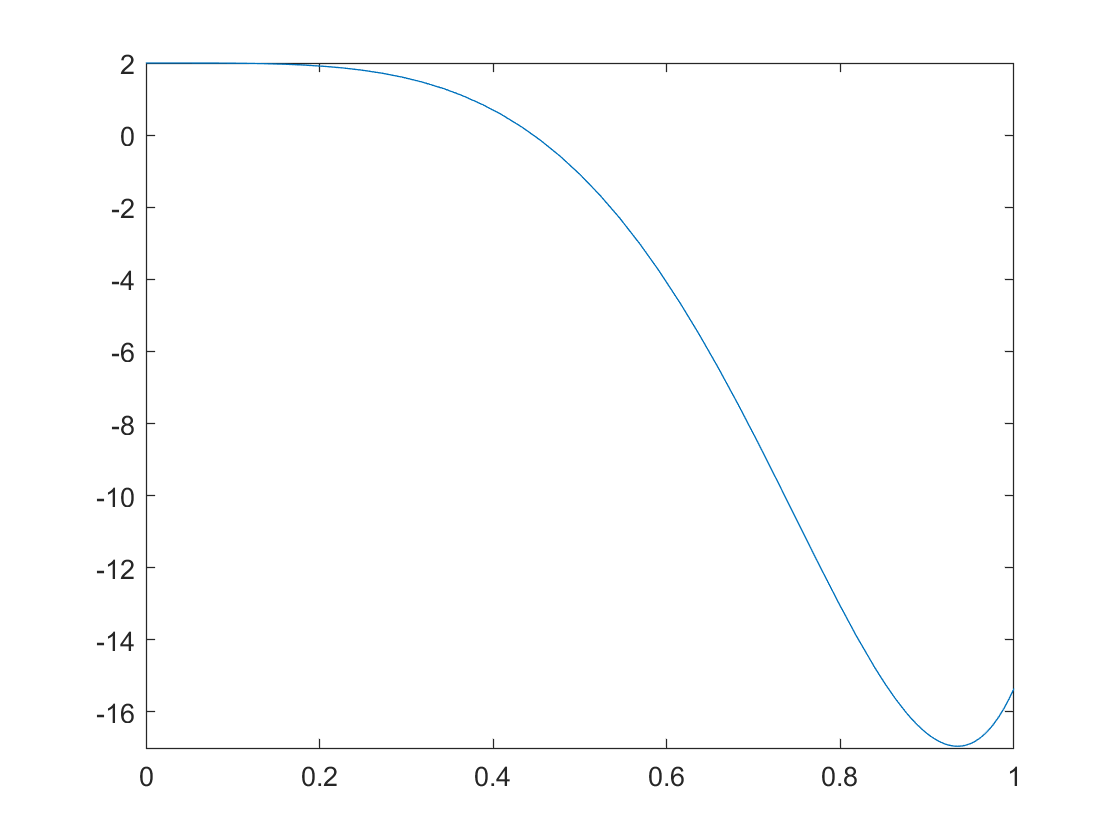

close all; clear all; clc;
L=4.2;
syms b
eqn = 1+cosh(b*L)*cos(b*L)==0;
% through the figure to have an initial guess
fplot(@(b) 1+cos(b*L).*cosh(b*L),[0,1])

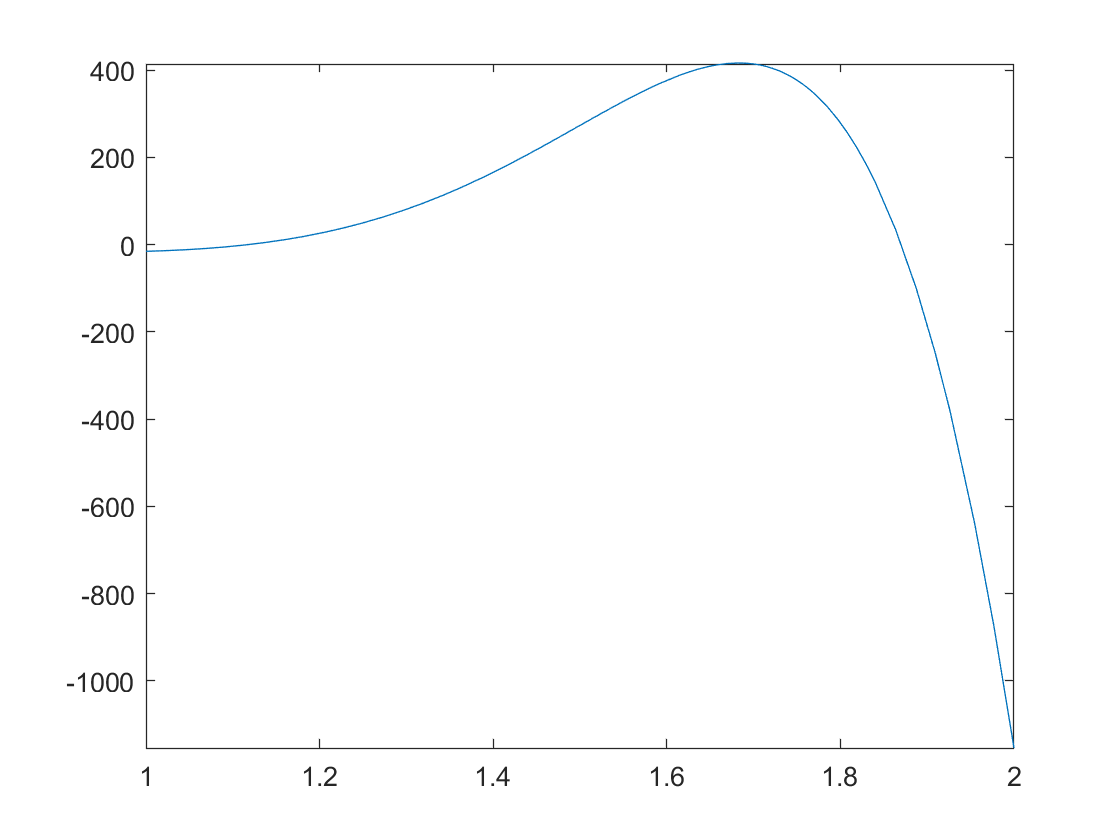

fplot(@(b) 1+cos(b*L).*cosh(b*L),[1,2])

% from the figure, I found that there're two solutions, one within the
% interval of [0, 1], the other within the interval of [1, 2]
b1=vpasolve(eqn,b,[0 1])

$$b1 = 0.44645334969332408724888291454243$$

b2=vpasolve(eqn,b,[1,1.5])

$$b2 = 1.1176407459462320420086647090523$$

calculate the frequencies

EI=21000;
p=0.53;
b=[b1 b2];
w=b.^2*sqrt(EI/p)

$$w = \left(\begin{array}{cc} 39.675634803887490054448730222224 & 248.64295904550638119160105652525 \end{array}\right)$$

Problem 3

close all; clear all; clc;
x=1:10;
x=log(x);
x1=linspace(1,1,10);
A=[x' x1']

A =          0    1.0000
    0.6931    1.0000
    1.0986    1.0000
    1.3863    1.0000
    1.6094    1.0000
    1.7918    1.0000
    1.9459    1.0000
    2.0794    1.0000
    2.1972    1.0000
    2.3026    1.0000


y=[10 14 16 18 19 20 21 22 23 23];
S=lsqr(A,y');

lsqr converged at iteration 2 to a solution with relative residual 0.011.


a1=S(2);

a1 = 9.9123

a2=S(1);

a2 = 5.7518

Problem 4 

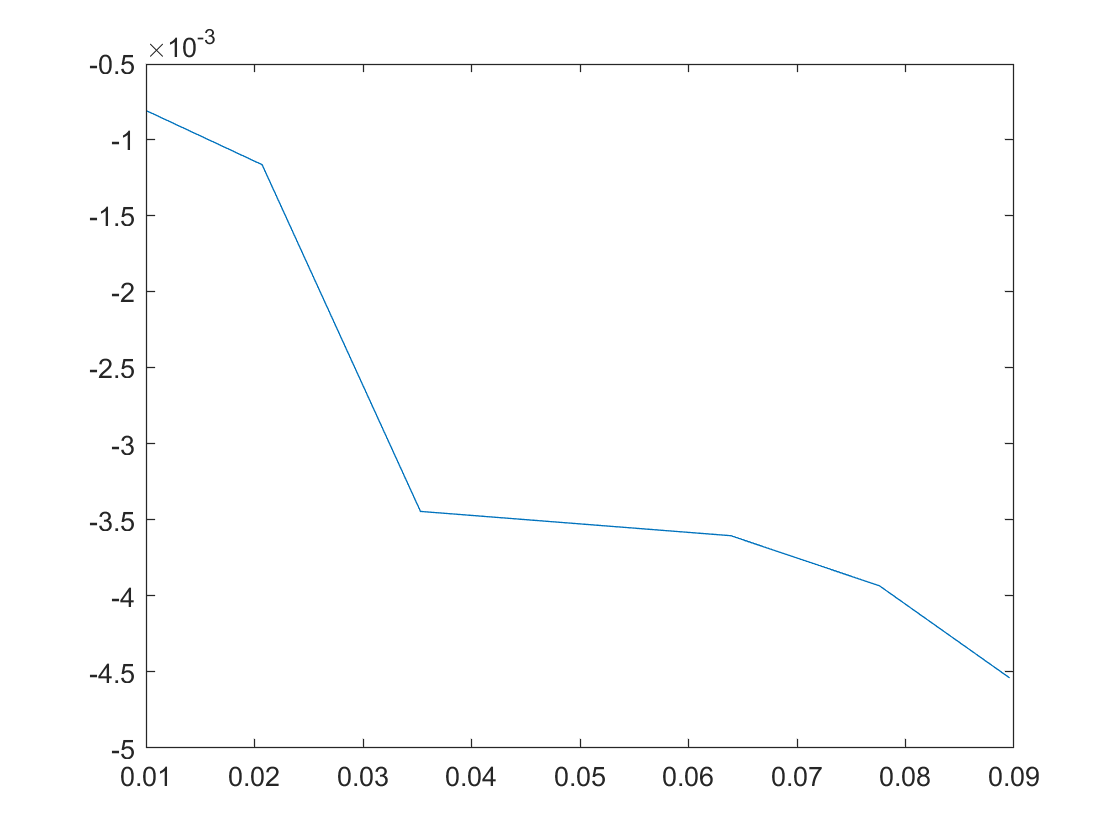

close all; clear all; clc;
t=[0 3.15 6.20 10.0 18.3 30.8 43.8];
C=[0.1039 0.0896 0.0776 0.0639 0.0353 0.0207 0.0101];
% calculate the rate of Change
rate_of_Change = zeros(1,size(t,2));
for i = 2:size(rate_of_Change,2)
    rate_of_Change(1,i)=(C(i)-C(i-1))/(t(i)-t(i-1));
end
% abort the first data, we cannot calculate what is the rate of change when
% t=0
b=rate_of_Change(1,2:size(t,2))';
A=C(1,2:size(t,2))';
plot(A,b)

% use least-sqaures fit to estimate the value of k
k=lsqr(A,b)

lsqr converged at iteration 1 to a solution with relative residual 0.2.


k = -0.0551

Problem 5

close all; clear all; clc;
% a
t=[1:10];
psi=[26.1 27.0 28.2 29.0 29.8 30.6 31.1 31.3 31.0 30.5]

psi =    26.1000   27.0000   28.2000   29.0000   29.8000   30.6000   31.1000   31.3000   31.0000   30.5000


% fit a first-degree polynomial
p1=polyfit(t,psi,1)

p1 =     0.5467   26.4533


f1=t*p1(1)+p1(2)

f1 =    27.0000   27.5467   28.0933   28.6400   29.1867   29.7333   30.2800   30.8267   31.3733   31.9200


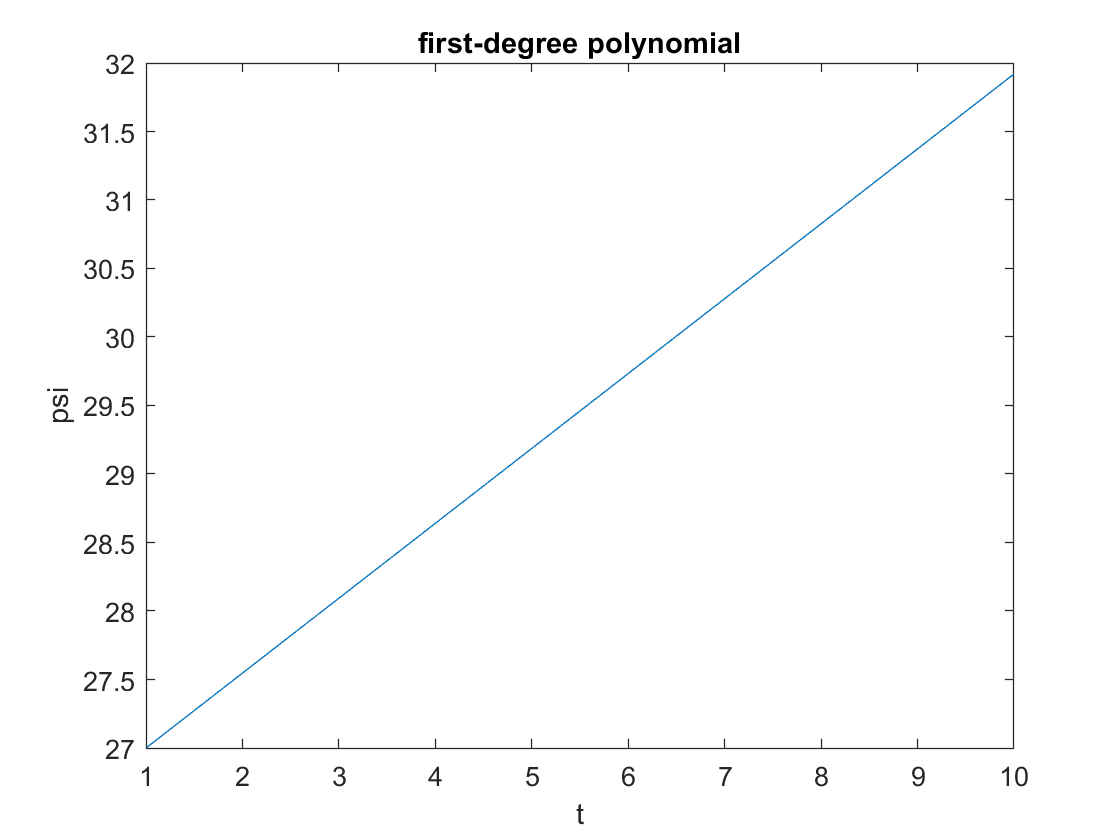

plot(t,f1)
xlabel('t')
ylabel('psi')
title('first-degree polynomial')


% fit a second-degree polynomial
p2=polyfit(t, psi, 2);
f2=t.^2*p2(1)+t*p2(2)+p2(3)

f2 =    25.8273   27.1558   28.2888   29.2264   29.9685   30.5152   30.8664   31.0221   30.9824   30.7473


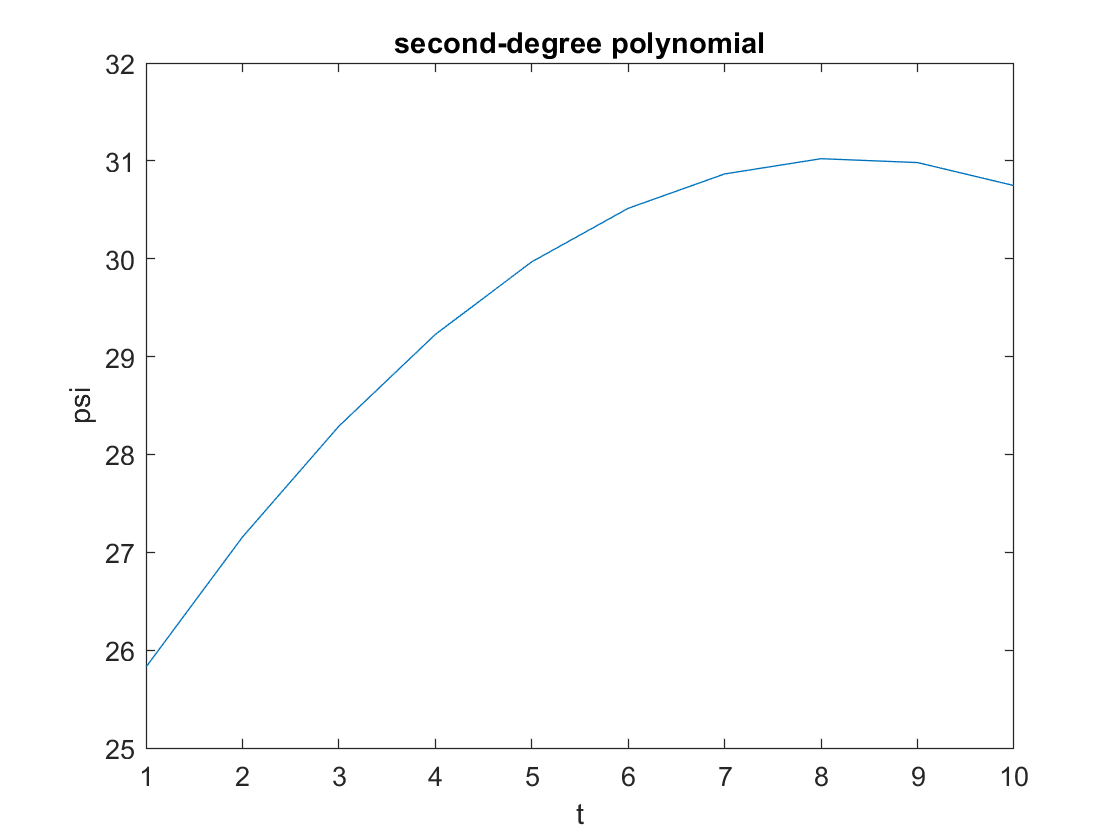

plot(t, f2)
xlabel('t')
ylabel('psi')
title('second-degree polynomial')

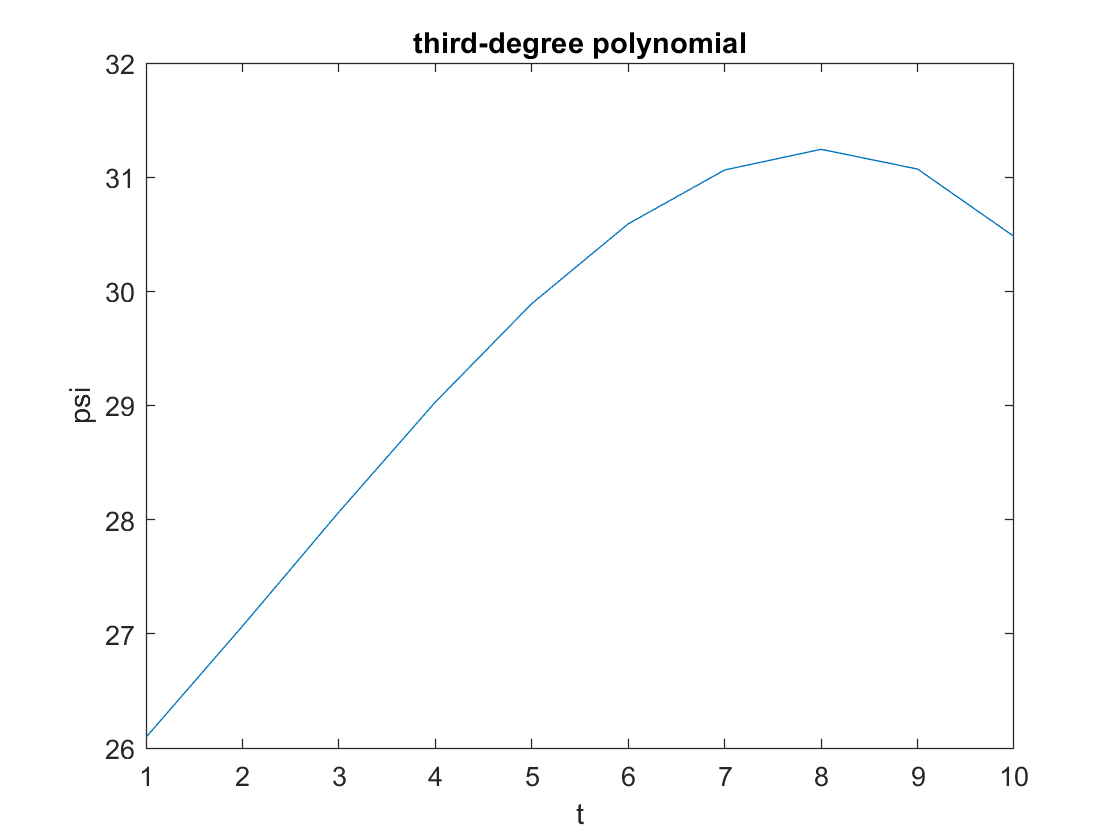


% fit a third-degree polynomial
p3=polyfit(t, psi, 3);
f3=t.^3*p3(1)+t.^2*p3(2)+t*p3(3)+p3(4);
plot(t, f3)
xlabel('t')
ylabel('psi')
title('third-degree polynomial')


% b
t=11;
psi1=t*p1(1)+p1(2)

psi1 = 32.4667

psi2=t.^2*p2(1)+t*p2(2)+p2(3)

psi2 = 30.3167

psi3=t.^3*p3(1)+t.^2*p3(2)+t*p3(3)+p3(4)

psi3 = 29.4100

residual_sum1=sum(abs(psi-f1))

residual_sum1 = 6.4800

residual_sum2=sum(abs(psi-f2))

residual_sum2 = 1.7733

residual_sum3=sum(abs(psi-f3))

residual_sum3 = 0.5208

deter_coeff1=cal_deter_coeff(f1, psi)

deter_coeff1 = 0.8195

deter_coeff2=cal_deter_coeff(f2, psi)

deter_coeff2 = 0.9871

deter_coeff3=cal_deter_coeff(f3, psi)

deter_coeff3 = 0.9986

curve 3 gives the most reliable prediction. It has the minimal residuals and the maximal coefficients of determination.

function deter_coeff = cal_deter_coeff(f, v)
    SStot=sum((mean(v)-v).^2);
    SSres=sum((f-v).^2);
    deter_coeff=1-SSres/SStot;
end